clear; clc;

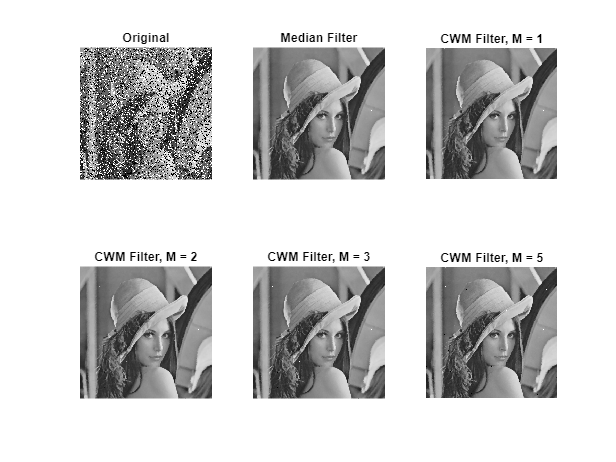

% Load the image
f = imread('Lena-salt-pepper-noise.bmp');

% Convert the image to grayscale
f = im2gray(f);

% Apply the median filter
g_median = median_filter(f);

% Apply the CWM filter with different values of M
M_values = [1, 2, 3, 5];
g_cwm = cell(1, numel(M_values));
for i = 1:numel(M_values)
    g_cwm{i} = cw_median_filter(f, M_values(i));
end

% Display the original image, the median filtered image, and the CWM filtered images
figure;
subplot(2, 3, 1); imshow(f); title('Original');
subplot(2, 3, 2); imshow(g_median); title('Median Filter');
for i = 1:numel(M_values)
    subplot(2, 3, i+2); imshow(g_cwm{i}); title(['CWM Filter, M = ', num2str(M_values(i))]);
end

## Function

function g = cw_median_filter(f, M)
    [height, width] = size(f); % size of input image
    g = zeros(height, width); % allocate memory for output image
    for y = 1:height
        for x = 1:width
            x1 = x - 2; % left column of the 5x5 window
            x2 = x + 2; % right column of the 5x5 window
            y1 = y - 2; % top row of the 5x5 window
            y2 = y + 2; % bottom row of the 5x5 window
            % When the neighborhood exceeds the image boundary, adjust coordinates
            x1 = max(x1, 1);
            x2 = min(x2, width);
            y1 = max(y1, 1);
            y2 = min(y2, height);
            window = f(y1:y2, x1:x2); % 5 x 5 window
            window = window(:); % rearrange window into a column vector
            center_pixel = f(y, x); % get the center pixel
            window = [window; repmat(center_pixel, M-1, 1)]; % repeat the center pixel M times
            g(y, x) = median(window); % output pixel = median of window 
        end
    end
    g = uint8(g); %imshow(g); % convert to 8-bit image and display
end